# **ACM 11 Homework 4 Part 3/3 (Spring 2024)**

## **Due Friday, May 24, 11:59pm Pacific Time, by upload to Canvas.**

This assignment consists of three parts. This final part is worth $20$ points. You should read the problem set-up in this file and follow the instructions to write and test your code. 

## Problem 8: Plotting the Euler Spiral (20 points)

An Euler spiral is a curve whose curvature grows linearly with the curve. Remarkably, this curve has a wide variety of engineering applications, including the design of track transition curves for racetracks, freeways, and railroads, the study of diffraction in optics, and the design of fonts and graphing tools in typography. The curve can be described parametrically in terms of two integral: 


$$X(t) = \int_0^t \cos(x^2) \ dx$$
 


$$Y(t) = \int_0^t \sin(x^2) \ dx$$


for $t \in (-\infty,\infty)$. These integrals are known as $\textbf{Fresnel integrals}$, named after the optical physicist who studied diffraction. An example is plotted in the figure below for $t \in [-40,40]$.

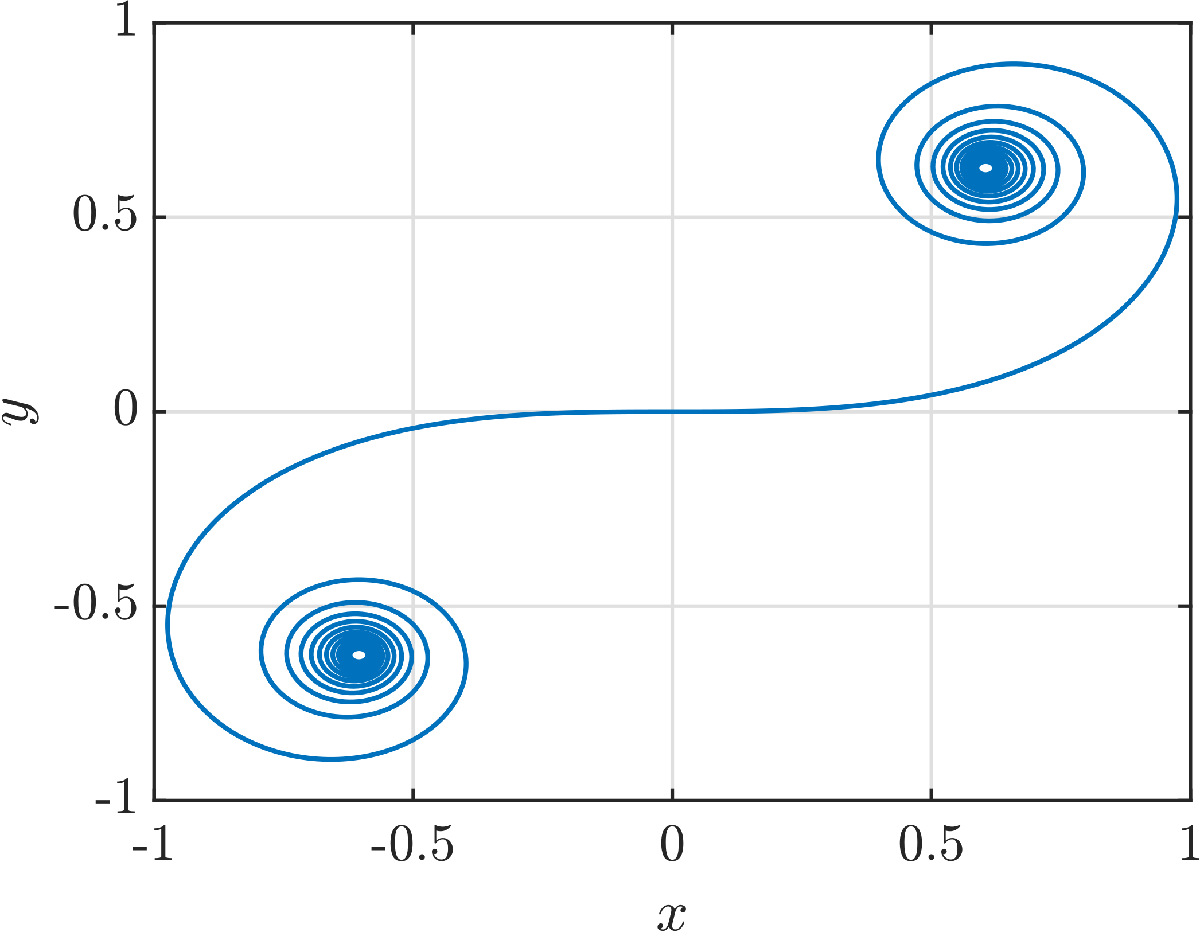

The Fresnel integrals do not have indefinite integrals that we can write down in terms of elementary functions. Typically, one must resort to approximations or numerical methods to compute these integrals. 

**Problem 8a (10 points): **We will first derive a quadrature rule for approximating integrals of the form $\int_0^1 f(z) \ dz$ in terms of three points $f(0), f(1), f(2)$, both points both inside and outside of our domain. Derive the weights $w_1,w_2,w_3$ in the following numerical integration formula:


$$\int_0^1 f(z) \ dz \approx w_1 f(0) + w_2 f(1) + w_3 f(2)$$


so that the integral is computed exactly for up to degree 2 polynomials such as$f(z) = z^0=1$, $f(z) = z^1$, and $f(z) = z^2$. 

(Hint: Set up a system of equations so that the left and right hand side of the equation involving the integral and quadrature approximation, respectively, is equal for these three polynomials: constant, linear and quadratic.)

**Problem 8b (5 points): **Recall that we can use the points and weights derived in 8a to compute an integral defined on an arbitrary interval $[a,b]$ using the simple transformation $x = (b-a)z + a$. That is,

    
$$\int_a^b f(x) \ dx = \int_0^1 f((b-a)z+a) \cdot (b-a) \ dz$$


Complete the `quadrature_threepts.m` function that uses the quadrature rule you derived above to approximate an integral with $N$ quadrature points. The function takes in:

- $f$, the function handle 

- the integration limits $a,b$

- the total number of quadrature points $N$. 

It will apply the quadrature rule defined above on $N/2$ sub-intervals, that each contain three integration points. Be sure to transform the points and weights so that you may compute any integral defined on $[a,b]$. 

**Problem 8c (5 points): **Complete the `eulerspiral.m` file to plot the Euler spiral (i.e., the Fresnel integrals) for $t \in [-40,40]$. The file uses the `quadrature_threepts` function to compute the integrals. Determine empirically the minimum number of quadrature points $N$ are needed to properly approximate the integral so the generated plot matches the figure above. 

fprintf(['Based on trial and error, it seems that the minimum number of quadrature points required to approximate \n' ...
    'the integral so the plot matches the figure above is about 1050, at which point the plot is pretty much smooth.'])

Based on trial and error, it seems that the minimum number of quadrature points required to approximate 
the integral so the plot matches the figure above is about 1050, at which point the plot is pretty much smooth.

What happens when you don't use enough quadrature points to compute this curve? What happens if you use too many?

fprintf(['When not using enough quadrature points to compute the curve, the graph is very jagged and spiky, (when it is \n' ...
    'close to but still less than 1050). However, when N is much smaller than 1050, the plot shows two spirals closer to the \n' ...
    'middle of the plot that eventually converge when N is much smaller. When too many quadrature points are used, it takes much \n' ...
    'longer to generate the plot and the spirals become much tighter.'])

When not using enough quadrature points to compute the curve, the graph is very jagged and spiky, (when it is 
close to but still less than 1050). However, when N is much smaller than 1050, the plot shows two spirals closer to the 
middle of the plot that eventually converge when N is much smaller. When too many quadrature points are used, it takes much 
longer to generate the plot and the spirals become much tighter.

## **Problem 9: Time Spent (0 points)**

How many hours did you spend on this homework, part 3? Please round to the nearest half hour. 

hours = 1;